作图：在同一图中显示正弦函数y1=sin(x)与直线y2=-x+0.5,

要求显示标题、横坐标标签、纵坐标标签、图例，对y1、y2做文本标注。

x取值[-2*pi,2*pi],然后通过解方程组将解在图中用星号标注

syms y;
y1 = @(x)sin(x);
y2 = @(x)0.5 - x;
x = -2*pi:0.1:2*pi;
plot(x,y1(x),x,y2(x),'r-');
hold on;
eqn = sin(y)+y-0.5;
r = vpasolve(eqn == 0,y);
text(r,y2(r),'*');
legend('sinx','-x+0.5');
xlabel('XAxis')
ylabel('YAxis')
title('$y_1=sin(x)$ $y_2=-x+0.5$','Interpreter','latex')
grid on;

在第1个子窗口用极坐标画图显示r=0.5(1+cos（θ）)，其中θ∈[0,2π]；

在第2个子窗口作填充图，填充坐标矢量为X=[0 0.2 0.8 1 0.5 0],Y=[1 0 0 1 1.8 1],填充颜色为蓝色；

在第3个子窗口作双y轴图y1=sin（t），t∈[0,4π]，y2=20*cos(t);

在第4个子窗口显示相图x=sin（t），y=cos(t)

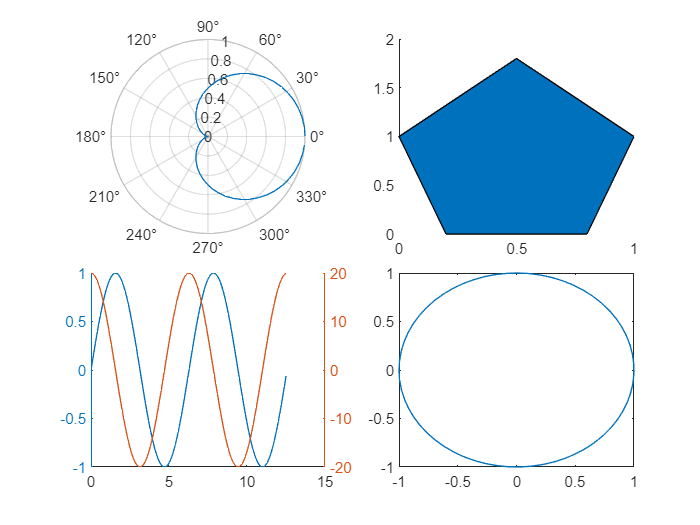

%按Ctrl+e显示上面效果

tiledlayout(2,2,'TileSpacing','compact');

g1 = nexttile;
theta = 0:0.1:2*pi;
rho = 0.5*(1+cos(theta));
polarplot(theta,rho)

g2 = nexttile;
% X=[0 0.2 0.8 1 0.5 0];
% Y=[1 0 0 1 1.8 1];
X1 = [0 0.5 1];
Y1 = [1 1.8 1];
X2 = [0 0.2 0.8 1];
Y2 = [1 0 0 1];
hold on
area(X1,Y1)
area(X2,Y2,'FaceColor',[1 1 1])

g3 = nexttile;
t = 0:0.1:4*pi;
y1 = sin(t);
y2 = 20*cos(t);
hold on
yyaxis('left')
plot(t,y1)
yyaxis('right')
plot(t,y2)

g4 = nexttile;
xx = sin(t);
yy = cos(t);
plot(xx,yy)
hold off